% Define file path (Update with your actual file location)
filePath = "C:\Users\dhiid\Downloads\tracking_data.csv";

% Read the CSV file into a table
data = readtable(filePath);

% Display first few rows to check structure
disp(data(1:5, :));

      Var1       Var2      Var3     Var4      Var5 
    ________    ______    ______    _____    ______

    0.034077    402.21    219.47    451.7    267.28
    0.048081    402.21    219.47    451.7    267.28
    0.062665    402.21    219.47    451.7    267.28
    0.077478    402.21    219.47    451.7    267.28
    0.091252    402.21    219.47    451.7    267.28



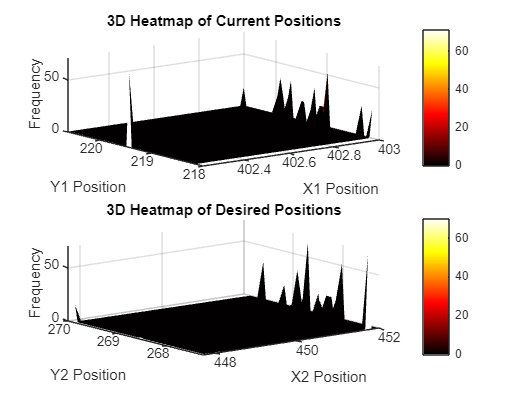


% Extract data (modify column indices if necessary)
x1 = data{:, 2}; % Current X values (actual system output)
y1 = data{:, 3}; % Desired X values (setpoint)  
x2 = data{:, 4}; % Current Y values (actual system output)
y2 = data{:, 5}; % Desired Y values (setpoint) 

% Define number of bins
numBins = 50;

% Get 2D histogram counts for both datasets
[counts1, xedges1, yedges1] = histcounts2(x1, y1, numBins); 
[counts2, xedges2, yedges2] = histcounts2(x2, y2, numBins);

% Compute bin centers for proper plotting
X1 = (xedges1(1:end-1) + xedges1(2:end)) / 2;
Y1 = (yedges1(1:end-1) + yedges1(2:end)) / 2;
[X1, Y1] = meshgrid(X1, Y1);

X2 = (xedges2(1:end-1) + xedges2(2:end)) / 2;
Y2 = (yedges2(1:end-1) + yedges2(2:end)) / 2;
[X2, Y2] = meshgrid(X2, Y2);

% Create figure
figure;

% Plot first 3D histogram (Current Positions)
subplot(2, 1, 1);  % First subplot
surf(X1, Y1, counts1', 'EdgeColor', 'none'); % Use surf for smooth 3D plot
colormap hot; % Heatmap color
colorbar;
xlabel('X1 Position');
ylabel('Y1 Position');
zlabel('Frequency');
title('3D Heatmap of Current Positions');
view(3); % Set 3D view

% Plot second 3D histogram (Desired Positions)
subplot(2, 1, 2);  % Second subplot
surf(X2, Y2, counts2', 'EdgeColor', 'none'); % Use surf for smooth 3D plot
colormap hot; % Heatmap color
colorbar;
xlabel('X2 Position');
ylabel('Y2 Position');
zlabel('Frequency');
title('3D Heatmap of Desired Positions');
view(3); % Set 3D view